# Exercise: Multibody

**Author F. Biral**

**date: 04/6/2026**

A spray-bottle head is made up of a trigger lever, which activates a small pump. The main moving element of the pump is a piston, housed inside a cylinder and restrained by a small spring. The pump is operated pulling the trigger back which, pushes the piston into the cylinder (downstroke).The downstroke, the piston pushing in, shrinks the area of the cylinder, forcing fluid down a narrow barrel and out a small hole at the gun's muzzle. The hole, or nozzle, serves to focus the flowing liquid so that it forms a concentrated stream. At the same time the outward force of the moving fluid pushes the ball into the seal, blocking off the passageway to the reservoir. The upstroke, the spring pushing the piston back out, expands the cylinder area, sucking fluid into the pump. When the lever is completely released the spring is in its natural

position.

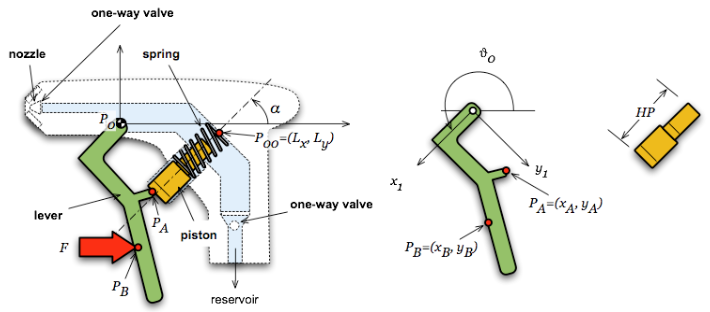

The piston movement is constrained along a linear guide tilted α w.r.t. fixed frame and is subject to columb friction (with µ*s *= 0.2, µ*d*= 0.1). The point  $P_A$ of the lever slides on the piston surface (and it is alway in touch with it due to the spring). The finger force F is applied horizontally on the point $P_A$ of the lever. The initial angular position of the frame moving with the lever (see picture on the right) is  $\theta = 200\degree $.

data := [Lx = 0.025 , Ly = -0.01, HP = 0.015 , alpha = 25°, xA = 0.004, yA = 0.021 , xB = 0.013, yB = 0.04 ]

**Study the kinematics of the system and drive the equations of motion**

## **List of available command**

There is a collection of functions to ease the process of deriving the equations of kinematics and teh equations of motion. To use it you have to add the path to the folder with: `addpath('MBLibs');`

- `rotate('Z',theta_x(t)): `creates a 4 x 4 transformation matrix with the 3 x3 rotation matrix and origin [0,0,0]

- `rotate3('Z',theta_x(t)): `creates a 3 x 3  rotation matrix 

- `translate([t_x;t_y;t_z]): `creates a 4 x 4 transformation matrix with the 3 x3 identiy matrix and origin [tx,ty,tz]

- `rotate3('Z',theta_x(t)): `creates a 3 x 3 rotation matrix

- `get_unit_vector('X',TM):` returns a 4x1 column vector of the rotation matrix

- `get_unit_vector('X',RM):` returns a 3x1 column vector of the rotation matrix

- `get_rotation_matrix(TM): return` a 3 x 3 rotation matrix 

- `get_origin(TM): `return the 4 x 1 vector of the TM transformation matrix

- `skew_matrix(v): `return the skew matrix given a vector `v` 1x3 

- `inv_frame(TM):`  make the inverse of a 4 x 4 Transformation Matrix

- `inv_rot_mat(RM): `make the transpose of a 3 x 3 rotation matrix

clear all 
close all
clc

addpath('MBLibs');

## Linear Graph and Normal tree

The picture shows the reference frames and joints. In particular the cam joint is a combined jojnt between a prismatic and a revolute joint.

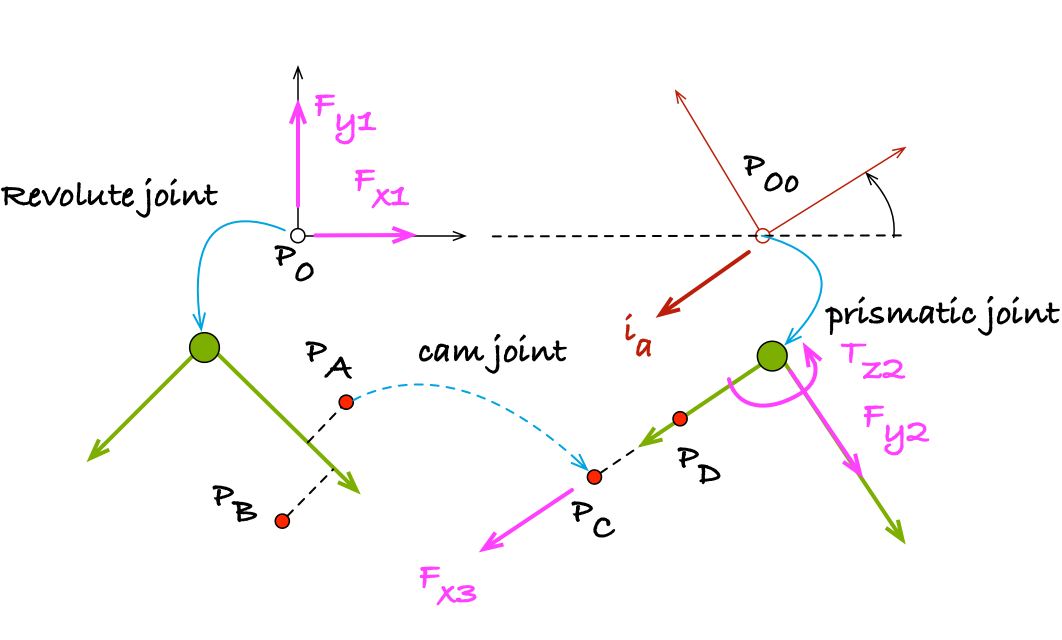

**The reaction forces of the joints are in the direction of the eliminated relative degres of fredom by the joint. Those direction are also called ****Reaction space****. This is also the reason to project the loop of the cut joint in the reaction space.**

The Linear Graph and the normal tree is in this picture. It is the overall LG with also the external forces.

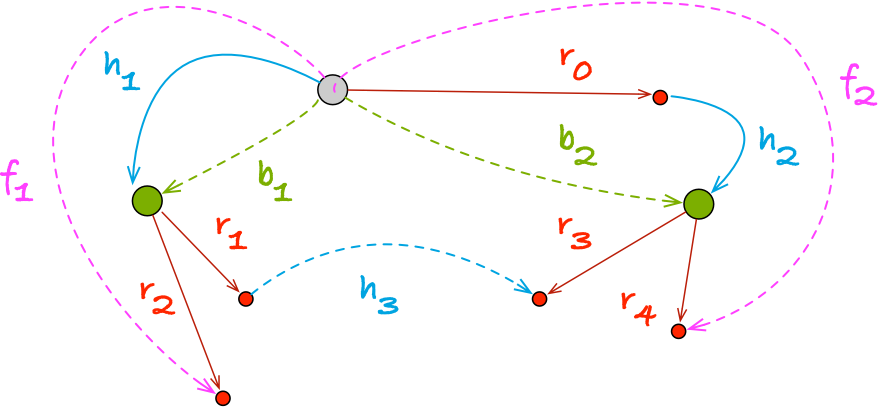

We split between the translational tree (T-Graph) and the rotational tree (R-Tree).  

The **T-tree** involves the joints and the arm-links. It has only one loop which is cut on the cam joint (dash line)

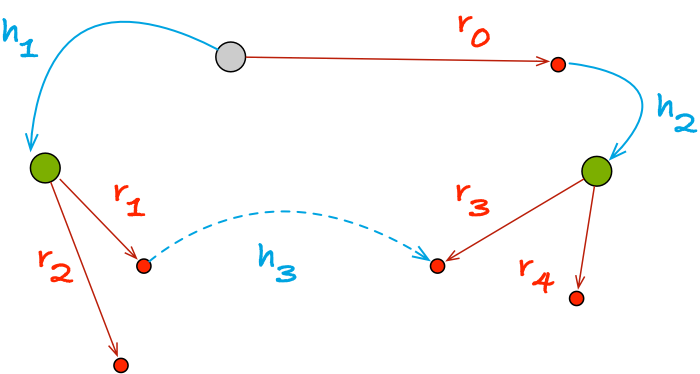

The R-Graph involves only the rotations and is as follows

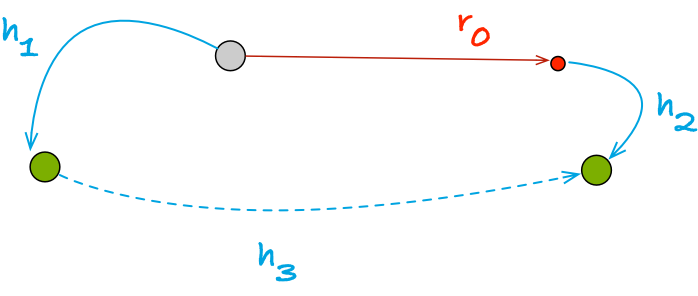

In this case the arm link $r_0$ because it involves a rotation in the absolute frame of an angle $\alpha$.

Remenber that in the R-Graph the loops that involves the bodies let us find  the joint angle as the body absolute angles.

## Multibody system data and definition

syms t theta1(t) theta2(t) s(t) theta3(t)
syms x1(t) y1(t) x2(t) y2(t)

% Parameters
syms alpha L_x L_y x_A y_A x_B y_B H_P L_0

## Equations of kinematics 

### Kinematic constitutive equations of bodies and arm links

In term of kinematics:

- Constitutive equations of **bodies** means to define the rotation matrices of body frame with absolute angles and vector between body ference frame origin and ground frame origin in absolute coordinates.

- Constitutive equations of** arm links** means to define the auxliary reference frame (vector plus, if any, rotation matrix) between the body frame and the auxiliary frame. Then they must be transformed into absolute coordinates using the body rotation matrix

**Body 1**

% Rotation matrix of body frame 1 
R1 = rotate3('Z',theta1(t))

$$R1 = \left(\begin{array}{ccc} \cos\left(\theta_{1}\left(t\right)\right) & -\sin\left(\theta_{1}\left(t\right)\right) & 0\\ \sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

% vector of position of origin body 1 w.r.t. ground origin: absolute coordinates
b1 = [x1(t);y1(t);0];

**Body 2**

% Rotation matrix of body frame 2 
 R2 = rotate3('Z',theta2(t))

$$R2 = \left(\begin{array}{ccc} \cos\left(\theta_{2}\left(t\right)\right) & -\sin\left(\theta_{2}\left(t\right)\right) & 0\\ \sin\left(\theta_{2}\left(t\right)\right) & \cos\left(\theta_{2}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

% vector of position of origin body 1 w.r.t. ground origin: absolute coordinates
 b2 = [x2(t);y2(t);0];

**Arm links**

The arm link $r_0$ in ground frame defines both a translation adn a rotation with constant angle $\alpha$. Thus we have to define both the translation in ground frame and the corresponding rotation matrix.  The unit vectors of the rotation matrix also define the the direction of sliding axis $i_a$ and its orthogonal $j_a$ (ie. the joint **motion** and **reaction** spaces)

% Arm links on ground
r0 = [L_x;L_y;0];
% 
R0 = rotate3('Z',alpha+pi);
% unit vector of sliding axis: it defines the motion space of the joint
ia = get_unit_vector3('X',R0)

$$ia = \left(\begin{array}{c} -\cos\left(\alpha \right)\\ -\sin\left(\alpha \right)\\ 0 \end{array}\right)$$

% unit vector orthogonal to sliding axis: it defines the reaction space of
% the joint
ja = get_unit_vector3('Y',R0);

**Arm links of body 1**

For these two arm links in body 1 we define only the translational vector because there is no relative rotation between the corresponding auxiliary frame and the body frame. Just a pure translation. Thus the coordinates of the points Pa and PB locations in body frame coordinates are projected into ground frame with the body rotation matrix.

r1 = R1*[x_B;y_B;0];
r2 = R1*[x_A;y_A;0];

**Arm links of body 2**

For these two arm links in body 2 we define only the translational vector because there is no relative rotation between the corresponding auxiliary frame and the body frame. Just a pure translation. Thus the coordinates of the points PC and PD locations in body frame coordinates are projected into ground frame with the body rotation matrix. 

r3 = R2*[H_P;0;0];
r4 = R2*[L_0;0;0];

### Kinematic constitutive equations of joints

The constitutive equations of the joints in term of kinematics can be either:

- the allowed relative translations and rotations (i.e. vector and rotation matrix) 

- or the condtions that imposes the relative motion restriction

**Revolute joint**

The translational vector that defines the relative motion which is  allowed by the revolute jojnt. Thus is a zero components vector since the revolote joint does not allow the relative translation between the two origins of two frames connected by the joint

% translational constitutive equation of rev. joint
h1 = [0;0;0];

**Prismatic joint**

The translational vector that defines the relative motion which is  allowed by the primstaic jojnt. Thus is a  vector with a displacement s(t) along the sliding axis since the prismatic joint allows  a relative  translation between the two origins of two frames connected by the joint

% translational constitutive equation of rev. joint
h2 = s(t)*ia;

**Cam joint**

The joint has a relative translation along $j_a$  (y(t)) and a rotation around the z-axis. Instead in does not allow the relative translation along  axis $i_a$ . However, we will project the constrant equation  into the reaction space of the jojnt in order to not involve the coordinate y(t).

syms y(t) % it is defined but not used
% translational constitutive equation of rev. joint: it has a traslation
% along ja and a rotation around Z-axis.
h3 = y(t)*ja

$$h3 = \left(\begin{array}{c} \sin\left(\alpha \right)\,y\left(t\right)\\ -\cos\left(\alpha \right)\,y\left(t\right)\\ 0 \end{array}\right)$$

Normaly we shold also write the rotation matrices of the joints, but it is not necessary 

### Loop equations: constraint equations

### R-Graph

The rotational graph in 2D is the sum of the rotation around the kinematic chain

One option is to use the same tree of the T-graph however this will introduce the angle theta3(t)

Phi_theta2A = theta3(t) == alpha+pi-theta1(t)

$$Phi\_theta2A = \theta_{3}\left(t\right)=\alpha +\pi -\theta_{1}\left(t\right)$$

The other is the loop involving body 2, which tells us that the bdy is fixed

Phi_theta2 = theta2(t) == 0+alpha+pi

$$Phi\_theta2 = \theta_{2}\left(t\right)=\alpha +\pi$$

### T-Graph

The transaltional grah in 2D is the sum of the translational vector (edges) around the loop. There is only a loop and we cut the cam joint. Formally one can also write the vetcorial loop equal to zero.

Then we have to **project** the loop **in the reaction space of the cut joint**, thus the space of restrained relative motion

**Cam joint vector**

%eq_cut = h3 == r0+h2+r3-(r1+h1)
eq_cut = h3 - ( r0+h2+r3-(r1+h1) )  % we write as eq == 0 to allow the projection

$$eq\_cut = \left(\begin{array}{c} \cos\left(\alpha \right)\,s\left(t\right)-L_{x}+\sin\left(\alpha \right)\,y\left(t\right)+x_{B}\,\cos\left(\theta_{1}\left(t\right)\right)-y_{B}\,\sin\left(\theta_{1}\left(t\right)\right)-H_{P}\,\cos\left(\theta_{2}\left(t\right)\right)\\ \sin\left(\alpha \right)\,s\left(t\right)-H_{P}\,\sin\left(\theta_{2}\left(t\right)\right)-\cos\left(\alpha \right)\,y\left(t\right)-L_{y}+y_{B}\,\cos\left(\theta_{1}\left(t\right)\right)+x_{B}\,\sin\left(\theta_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

The translational loop vector of the joint must be projected into the reaction space of the join

Phi = simplify(expand(eq_cut.'*ia))

$$Phi = H_{P}\,\cos\left(\alpha -\theta_{2}\left(t\right)\right)-s\left(t\right)-x_{B}\,\cos\left(\alpha -\theta_{1}\left(t\right)\right)-y_{B}\,\sin\left(\alpha -\theta_{1}\left(t\right)\right)+L_{x}\,\cos\left(\alpha \right)+L_{y}\,\sin\left(\alpha \right)$$

% we substitute the theta2(t) angle
Phi = subs( Phi,lhs(Phi_theta2),rhs(Phi_theta2))

$$Phi = L_{x}\,\cos\left(\alpha \right)-s\left(t\right)-x_{B}\,\cos\left(\alpha -\theta_{1}\left(t\right)\right)-y_{B}\,\sin\left(\alpha -\theta_{1}\left(t\right)\right)-H_{P}+L_{y}\,\sin\left(\alpha \right)$$

We can also find the analytical solution for s(t)

syms y 
tmp = subs( Phi, s(t), y);
sol_s = solve(tmp,y)

$$sol\_s = L_{x}\,\cos\left(\alpha \right)-x_{B}\,\cos\left(\alpha -\theta_{1}\left(t\right)\right)-y_{B}\,\sin\left(\alpha -\theta_{1}\left(t\right)\right)-H_{P}+L_{y}\,\sin\left(\alpha \right)$$

If it is not possible to solve it analytically it will be added to the DAE system of equations of dynamics

## Equations of Dynamics

**NOTE**: Since we do not have to differentiate the forces then we do not add (t) dependency on time. Thus it will be easier to use `solve() `command. Otherwiese we are forced to do a formal substitution of the variable (e.g. x(t) --> y_1 ) as above

### Constitutive equations 

From the point of view of dynamics the constitutive equations are:

- **body**: are the Newton Euler equations. The Newton equations (i.e. translational balance) are defined in ground frame normalyThe Euler equations (i.e. moment balance) are defined in body frame

- **joints**: the constitutive equations of joints from dynamic point of view corresponde to the definition of the reaction forces in the reaction space.

**Bodies**

Newton equations

syms m1 Iz1 Fbx_1 Fby_1 Tbz_1  Fb1 Tb1 aG1

**Body 1**

Fb1 and Tb1 which are the total force and moment action on the body will be given by the node equations

% acceleration of centre of mass
aG1 = [0,0,0].';
Fb1 = [Fbx_1,Fby_1,0].'; % total force on body
Tb1  = [0,0,Tbz_1].';        % total torque on body

% Newton Euler equations for body 1
eqnN1 = m1*aG1== Fb1

$$eqnN1 = \left(\begin{array}{c} 0={\mathrm{Fbx}}_{1}\\ 0={\mathrm{Fby}}_{1}\\ 0=0 \end{array}\right)$$

% Euler equation for body 1: in body frame
eqnE1 = Iz1*[0,0,0].' ==-Tb1

$$eqnE1 = \left(\begin{array}{c} 0=0\\ 0=0\\ 0=-{\mathrm{Tbz}}_{1} \end{array}\right)$$

**Body 2**

Fb2 and Tb2 which are the total force and moment action on the body will be given by the node equations

syms Fbx_2 Fby_2 Tbz_2 m2 Iz2 Fb2 Tb2 aG2
% acceleration of centre of mass
aG2 = [0,0,0].';
Fb2 = [Fbx_2,Fby_2,0].'; % total force on body
Tb2 = [0,0,Tbz_2].'; % total torque on body

% Newton Euler equations for body 2
eqnN2 = m2*aG2 == -Fb2;
eqnE2 = Iz2*[0,0,0].' == -Tb2;

**Joints**

syms Fx_1 Fy_1  Fx_3  Fy_2 Tz_2

Definition of  generalised reaction forces in reaction space.

**NOTE**: they are **defined in the reaction space** but then projected to ground frame and for the moment balance projected into the body if used respectivelly in Newton or Euler equations

Frj1 = [Fx_1 Fy_1 0].';  % defined in reaction space and projected in ground frame
Fpj2 = R2*[0 Fy_2 0 ].'; % defined in reaction space and projected in ground frame
Tpj2 = R2*[0 0 Tz_2].';  % defined in reaction space and projected in ground frame
Fcj3 = R2*[Fx_3 0 0].';  % defined in reaction space and projected in ground frame 

**External forces**

Definition of external forces

syms Fe_x K

Fe = [Fe_x 0 0].';   % defined in the direction where they act and projected in ground frame
Fs = K*s(t)*ia(1:3)  % defined in the direction where they acts and projected in ground frame

$$Fs = \left(\begin{array}{c} -K\,\cos\left(\alpha \right)\,s\left(t\right)\\ -K\,\sin\left(\alpha \right)\,s\left(t\right)\\ 0 \end{array}\right)$$

### Node equations

In the node balance (cut-set) we assume positive the forces when the enter into the cut-set (drawn around the body). So if the edges of the graph enter into the cutset the force is taken positive. 

#### Translational balance

Node equations around body 1: we follow the same directiorn of the edges arrow. If they enter into the cut set is positive , if they exist is negative

eqns_node1_A = -Fb1+Frj1-Fcj3+Fe

$$eqns\_node1\_A = \left(\begin{array}{c} {\mathrm{Fe}}_{x}-{\mathrm{Fbx}}_{1}+{\mathrm{Fx}}_{1}-{\mathrm{Fx}}_{3}\,\cos\left(\theta_{2}\left(t\right)\right)\\ {\mathrm{Fy}}_{1}-{\mathrm{Fby}}_{1}-{\mathrm{Fx}}_{3}\,\sin\left(\theta_{2}\left(t\right)\right)\\ 0 \end{array}\right)$$

sol_Fb1 = solve([eqns_node1_A(1), eqns_node1_A(2)],[Fbx_1 Fby_1])

sol_Fb1 = struct with fields:
    Fbx_1: Fe_x + Fx_1 - Fx_3*cos(theta2(t))
    Fby_1: Fy_1 - Fx_3*sin(theta2(t))


Node equation around body 2

eqns_node2_A = -Fb2+Fpj2+Fcj3+Fs

$$eqns\_node2\_A = \left(\begin{array}{c} {\mathrm{Fx}}_{3}\,\cos\left(\theta_{2}\left(t\right)\right)-{\mathrm{Fy}}_{2}\,\sin\left(\theta_{2}\left(t\right)\right)-{\mathrm{Fbx}}_{2}-K\,\cos\left(\alpha \right)\,s\left(t\right)\\ {\mathrm{Fx}}_{3}\,\sin\left(\theta_{2}\left(t\right)\right)-{\mathrm{Fby}}_{2}+{\mathrm{Fy}}_{2}\,\cos\left(\theta_{2}\left(t\right)\right)-K\,\sin\left(\alpha \right)\,s\left(t\right)\\ 0 \end{array}\right)$$

sol_Fb2 = solve([eqns_node2_A(1), eqns_node2_A(2)],[Fbx_2 Fby_2])

sol_Fb2 = struct with fields:
    Fbx_2: Fx_3*cos(theta2(t)) - Fy_2*sin(theta2(t)) - K*cos(alpha)*s(t)
    Fby_2: Fx_3*sin(theta2(t)) + Fy_2*cos(theta2(t)) - K*sin(alpha)*s(t)


#### Rotational balance

We use the skew matrix to implement the vector product.

% Project the forces into the body frame and compute moments
eqns_node1_B = simplify(...
  Tb1 ...
-skew_matrix(r1)*inv_rot_mat(R1)*Fcj3 ...
+skew_matrix(r2)*inv_rot_mat(R1)*Fe)

$$eqns\_node1\_B = \left(\begin{array}{c} 0\\ 0\\ {\mathrm{Tbz}}_{1}+{\mathrm{Fx}}_{3}\,y_{B}\,\cos\left(2\,\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)+{\mathrm{Fx}}_{3}\,x_{B}\,\sin\left(2\,\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)-{\mathrm{Fe}}_{x}\,y_{A}\,\cos\left(2\,\theta_{1}\left(t\right)\right)-{\mathrm{Fe}}_{x}\,x_{A}\,\sin\left(2\,\theta_{1}\left(t\right)\right) \end{array}\right)$$

sol_Tb1 = solve(eqns_node1_B(3),Tbz_1)

$$sol\_Tb1 = {\mathrm{Fe}}_{x}\,y_{A}\,\cos\left(2\,\theta_{1}\left(t\right)\right)-{\mathrm{Fx}}_{3}\,x_{B}\,\sin\left(2\,\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)-{\mathrm{Fx}}_{3}\,y_{B}\,\cos\left(2\,\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)+{\mathrm{Fe}}_{x}\,x_{A}\,\sin\left(2\,\theta_{1}\left(t\right)\right)$$

% Project the forces into the body frame and compute moments
% the application point in on riging of b2 so prismatic force does not
% generate moment
eqns_node2_B = simplify(...
  Tb2 ...
 +Tpj2 ...
+skew_matrix(r4)*inv_rot_mat(R2)*Fcj3 ...
+skew_matrix(r3)*inv_rot_mat(R2)*Fs)

$$eqns\_node2\_B = \left(\begin{array}{c} 0\\ 0\\ {\mathrm{Tbz}}_{2}+{\mathrm{Tz}}_{2}-{\mathrm{Fx}}_{3}\,L_{0}\,\sin\left(\theta_{2}\left(t\right)\right)-H_{P}\,K\,\sin\left(\alpha -2\,\theta_{2}\left(t\right)\right)\,s\left(t\right) \end{array}\right)$$

sol_Tb2 = solve(eqns_node2_B(3),Tbz_2)

$$sol\_Tb2 = {\mathrm{Fx}}_{3}\,L_{0}\,\sin\left(\theta_{2}\left(t\right)\right)-{\mathrm{Tz}}_{2}+H_{P}\,K\,\sin\left(\alpha -2\,\theta_{2}\left(t\right)\right)\,s\left(t\right)$$

### Equations of motion

Asembling the equations and substituting the node equations we get the DAE equations

tmp = [eqnN1(1:2);eqnN2(1:2);eqnE1(3);eqnE2(3)];
tmp = subs(tmp,sol_Fb1);
tmp = subs(tmp,sol_Fb2);
tmp = subs(tmp,Tbz_1,sol_Tb1);
tmp = subs(tmp,Tbz_2,sol_Tb2);

DAEeqns = subs(tmp,sol_Tb1)

$$DAEeqns = \begin{array}{l} \left(\begin{array}{c} 0={\mathrm{Fe}}_{x}+{\mathrm{Fx}}_{1}-\sigma_{3}\\ 0={\mathrm{Fy}}_{1}-\sigma_{2}\\ 0={\mathrm{Fy}}_{2}\,\sin\left(\theta_{2}\left(t\right)\right)-\sigma_{3}+K\,\cos\left(\alpha \right)\,s\left(t\right)\\ 0=K\,\sin\left(\alpha \right)\,s\left(t\right)-{\mathrm{Fy}}_{2}\,\cos\left(\theta_{2}\left(t\right)\right)-\sigma_{2}\\ 0={\mathrm{Fe}}_{x}\,\sigma_{4}\,\left(\sigma_{6}+\sigma_{5}-\sigma_{1}-{\mathrm{Fe}}_{x}\,x_{A}\,\sigma_{4}\right)+\sigma_{6}+\sigma_{5}-\sigma_{1}\\ 0={\mathrm{Tz}}_{2}-{\mathrm{Fx}}_{3}\,L_{0}\,\sin\left(\theta_{2}\left(t\right)\right)-H_{P}\,K\,\sin\left(\alpha -2\,\theta_{2}\left(t\right)\right)\,s\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{Fe}}_{x}\,y_{A}\,\cos\left(2\,\theta_{1}\left(t\right)\right)\\ \sigma_{2}={\mathrm{Fx}}_{3}\,\sin\left(\theta_{2}\left(t\right)\right)\\ \sigma_{3}={\mathrm{Fx}}_{3}\,\cos\left(\theta_{2}\left(t\right)\right)\\ \sigma_{4}=\sin\left(2\,\theta_{1}\left(t\right)\right)\\ \sigma_{5}={\mathrm{Fx}}_{3}\,x_{B}\,\sin\left(\sigma_{7}\right)\\ \sigma_{6}={\mathrm{Fx}}_{3}\,y_{B}\,\cos\left(\sigma_{7}\right)\\ \sigma_{7}=2\,\theta_{1}\left(t\right)-\theta_{2}\left(t\right) \end{array}$$

With the constraint algebraic constrains

alg_eqns = [s(t) == sol_s; Phi_theta2]

$$alg\_eqns = \left(\begin{array}{c} s\left(t\right)=L_{x}\,\cos\left(\alpha \right)-x_{B}\,\cos\left(\alpha -\theta_{1}\left(t\right)\right)-y_{B}\,\sin\left(\alpha -\theta_{1}\left(t\right)\right)-H_{P}+L_{y}\,\sin\left(\alpha \right)\\ \theta_{2}\left(t\right)=\alpha +\pi \end{array}\right)$$

We can also substitute $s(t), \theta_2(t)$ that we have also calculated explicitly (solution of `alg_eqns` ) and we have that the equations are function only of  $ \theta_1(t)$

%sol_s
DAEeqns2 = subs( DAEeqns, {s(t),lhs(Phi_theta2)}, {sol_s,rhs(Phi_theta2)})

$$DAEeqns2 = \begin{array}{l} \left(\begin{array}{c} 0={\mathrm{Fe}}_{x}+{\mathrm{Fx}}_{1}+{\mathrm{Fx}}_{3}\,\cos\left(\alpha \right)\\ 0={\mathrm{Fy}}_{1}+{\mathrm{Fx}}_{3}\,\sin\left(\alpha \right)\\ 0={\mathrm{Fx}}_{3}\,\cos\left(\alpha \right)-{\mathrm{Fy}}_{2}\,\sin\left(\alpha \right)-K\,\cos\left(\alpha \right)\,\sigma_{1}\\ 0={\mathrm{Fy}}_{2}\,\cos\left(\alpha \right)+{\mathrm{Fx}}_{3}\,\sin\left(\alpha \right)-K\,\sin\left(\alpha \right)\,\sigma_{1}\\ 0=\sigma_{4}-\sigma_{5}-{\mathrm{Fe}}_{x}\,\sigma_{3}\,\left(\sigma_{5}-\sigma_{4}+\sigma_{2}+{\mathrm{Fe}}_{x}\,x_{A}\,\sigma_{3}\right)-\sigma_{2}\\ 0={\mathrm{Tz}}_{2}+{\mathrm{Fx}}_{3}\,L_{0}\,\sin\left(\alpha \right)-H_{P}\,K\,\sin\left(\alpha \right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=H_{P}+x_{B}\,\cos\left(\alpha -\theta_{1}\left(t\right)\right)+y_{B}\,\sin\left(\alpha -\theta_{1}\left(t\right)\right)-L_{x}\,\cos\left(\alpha \right)-L_{y}\,\sin\left(\alpha \right)\\ \sigma_{2}={\mathrm{Fe}}_{x}\,y_{A}\,\cos\left(2\,\theta_{1}\left(t\right)\right)\\ \sigma_{3}=\sin\left(2\,\theta_{1}\left(t\right)\right)\\ \sigma_{4}={\mathrm{Fx}}_{3}\,x_{B}\,\sin\left(\sigma_{6}\right)\\ \sigma_{5}={\mathrm{Fx}}_{3}\,y_{B}\,\cos\left(\sigma_{6}\right)\\ \sigma_{6}=\alpha -2\,\theta_{1}\left(t\right) \end{array}$$

rvars = [Fx_1 Fy_1  Fx_3  Fy_2 Tz_2 Fe_x]

$$rvars = \left(\begin{array}{cccccc} {\mathrm{Fx}}_{1} & {\mathrm{Fy}}_{1} & {\mathrm{Fx}}_{3} & {\mathrm{Fy}}_{2} & {\mathrm{Tz}}_{2} & {\mathrm{Fe}}_{x} \end{array}\right)$$

% We check that the number of equations correspond to the number of unknown
length(rvars)==length(DAEeqns2)

ans = logical
   1


We can solve the equations for two problems:

- **direct dynamics**: given $F_{e_x}$ for the reaction forces and the angle  $ \theta_1(t)$

- **inverse dynamics**: given the angle  $ \theta_1(t)$  for the reaction forces and $F_{e_x}$

Example: inverse dynamics

sol_inv_dyn = solve(DAEeqns2,rvars);
sol_inv_dyn.Fe_x